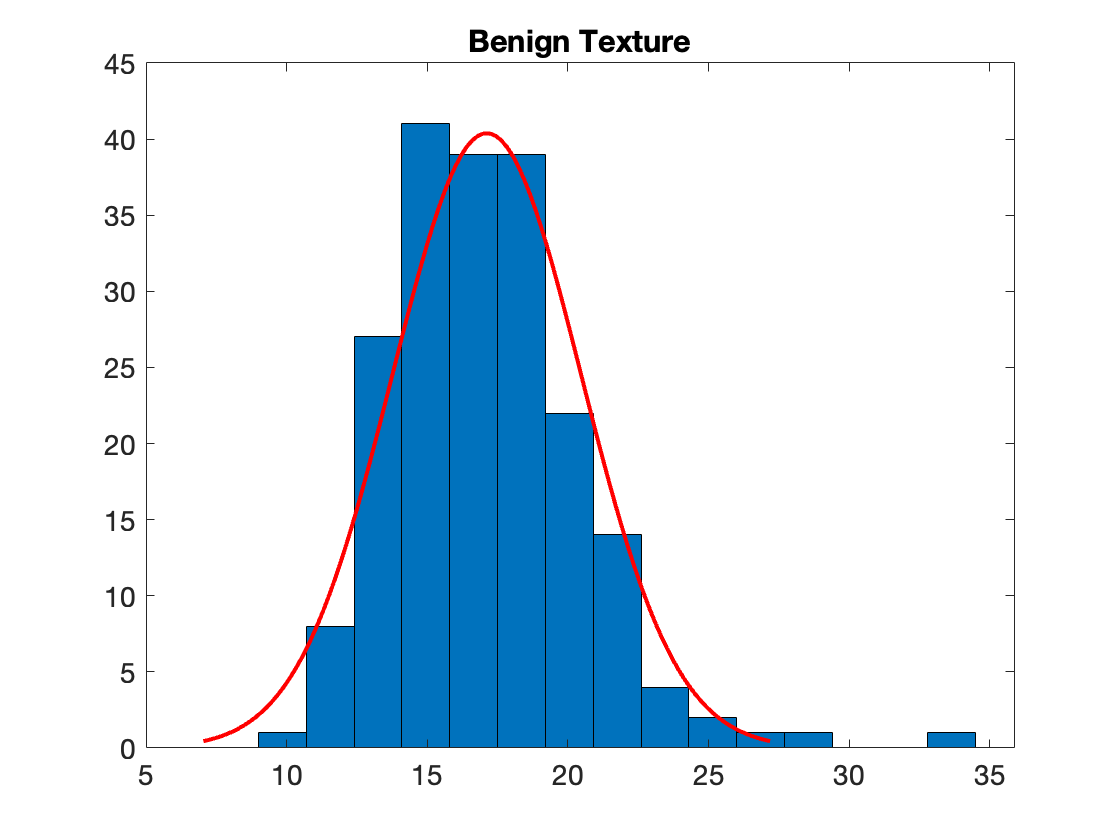

benign = readmatrix("benigndata.csv");
malignant = readmatrix("malignantdata.csv");

%%Question 4.6 
% 
% (a)
ben_mean = mean(benign);
mal_mean = mean(malignant);

% (b)
ben_var = var(benign);
mal_var = var(malignant);

% (c)
figure(1)
histfit(benign(:,1))
set(gca,'Fontsize',14);
title('Benign Texture')

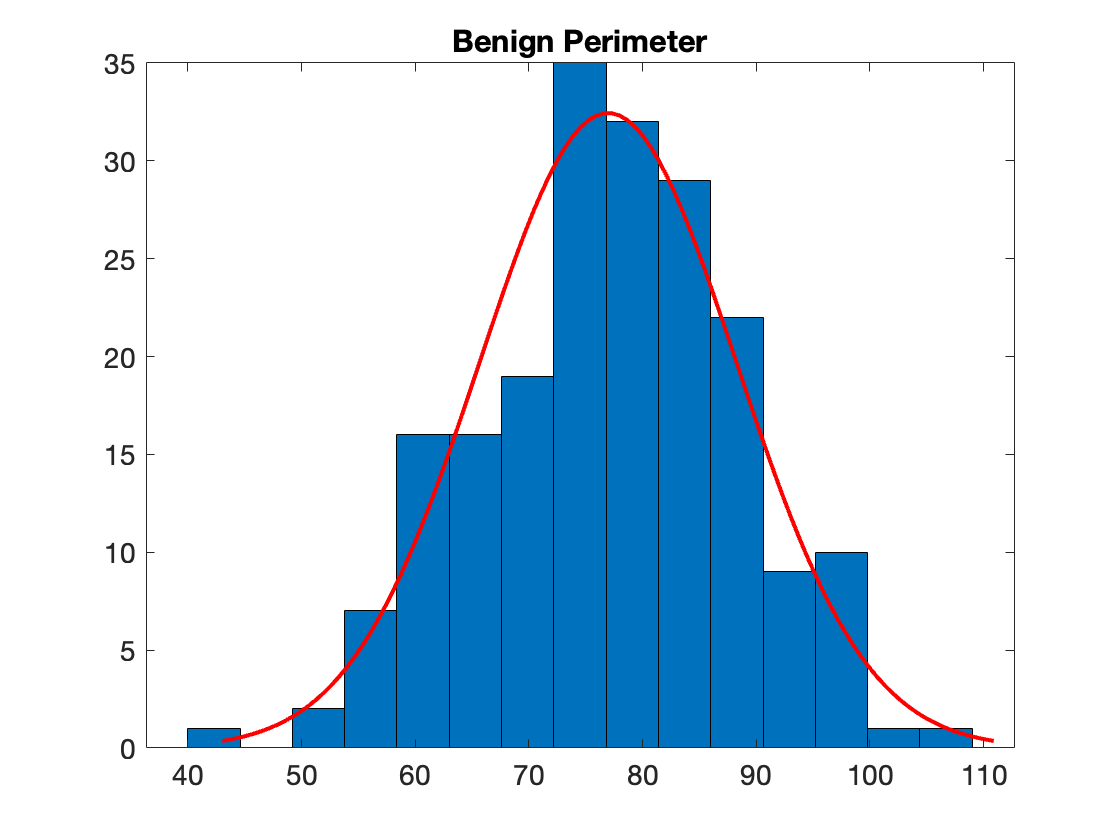


figure(2)
histfit(benign(:,2))
set(gca,'Fontsize',14);
title('Benign Perimeter')

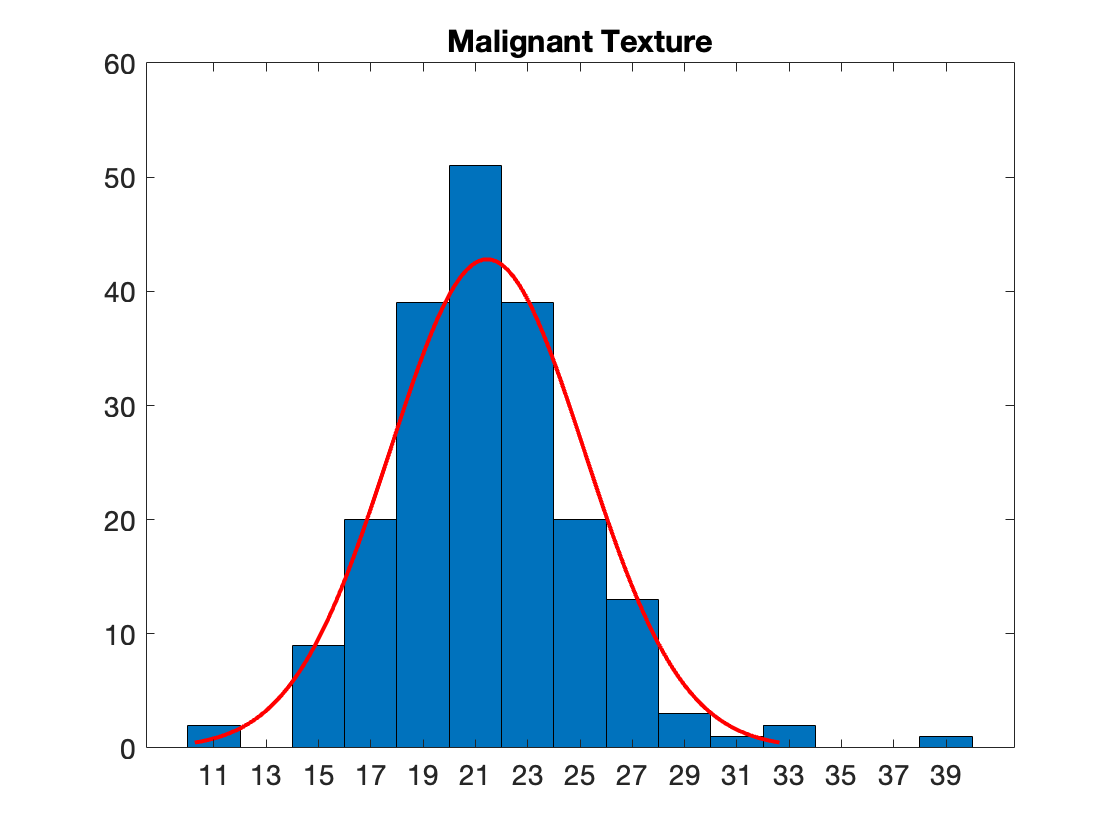


figure(3)
histfit(malignant(:,1))
set(gca,'Fontsize',14);
title('Malignant Texture')

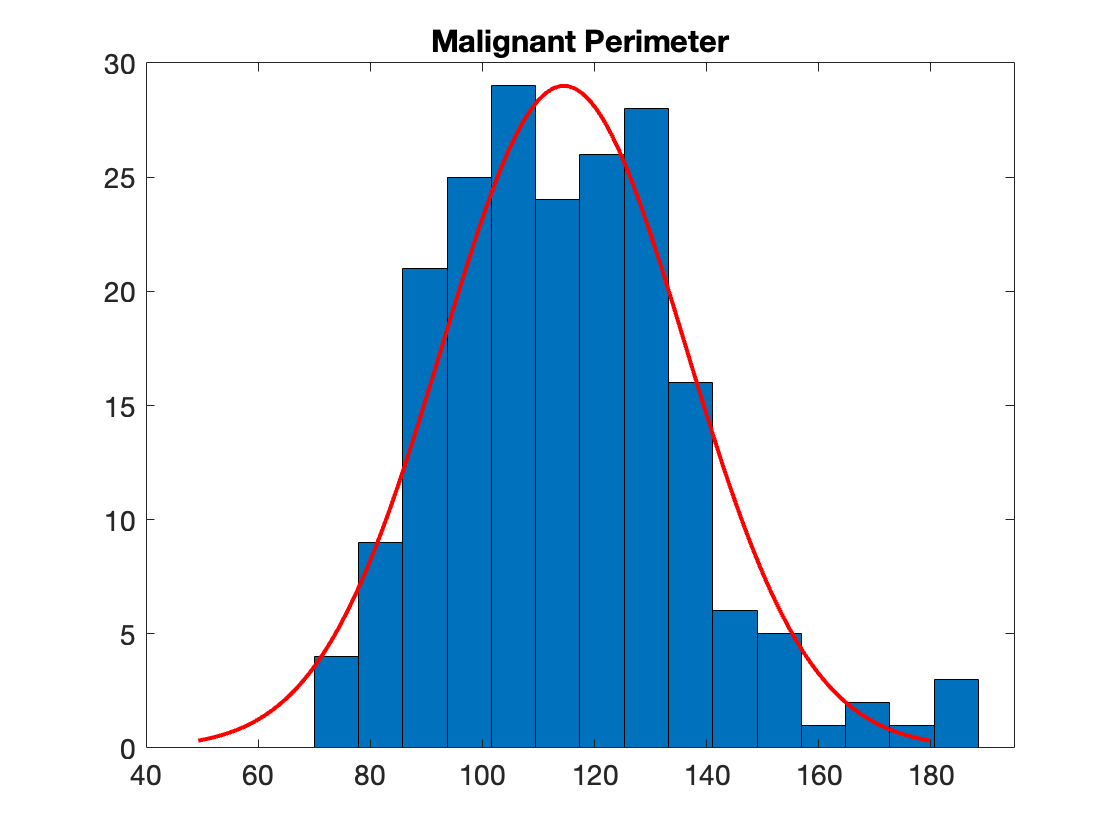


figure(4)
histfit(malignant(:,2)) 
set(gca,'Fontsize',14);
title('Malignant Perimeter')

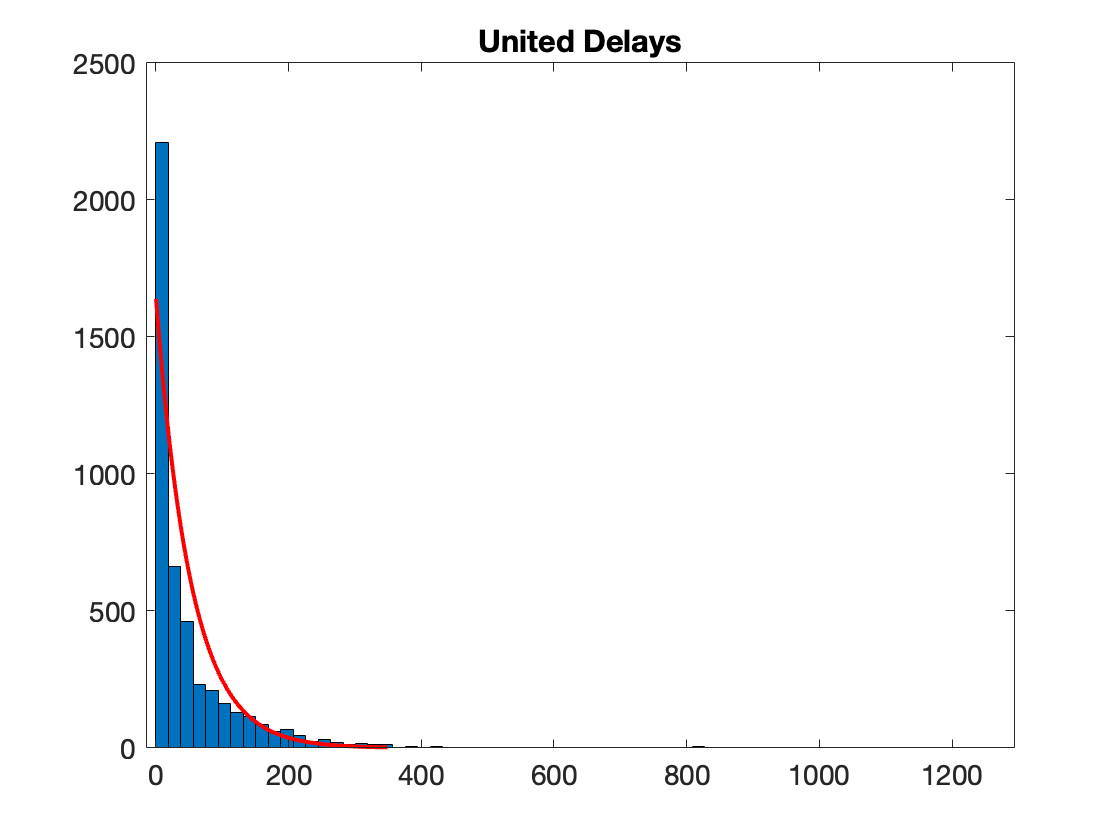


% (d)
Z = readmatrix("uniteddelays.csv");
histfit(Z,[],'exponential')
set(gca,'Fontsize',14);
title('United Delays')

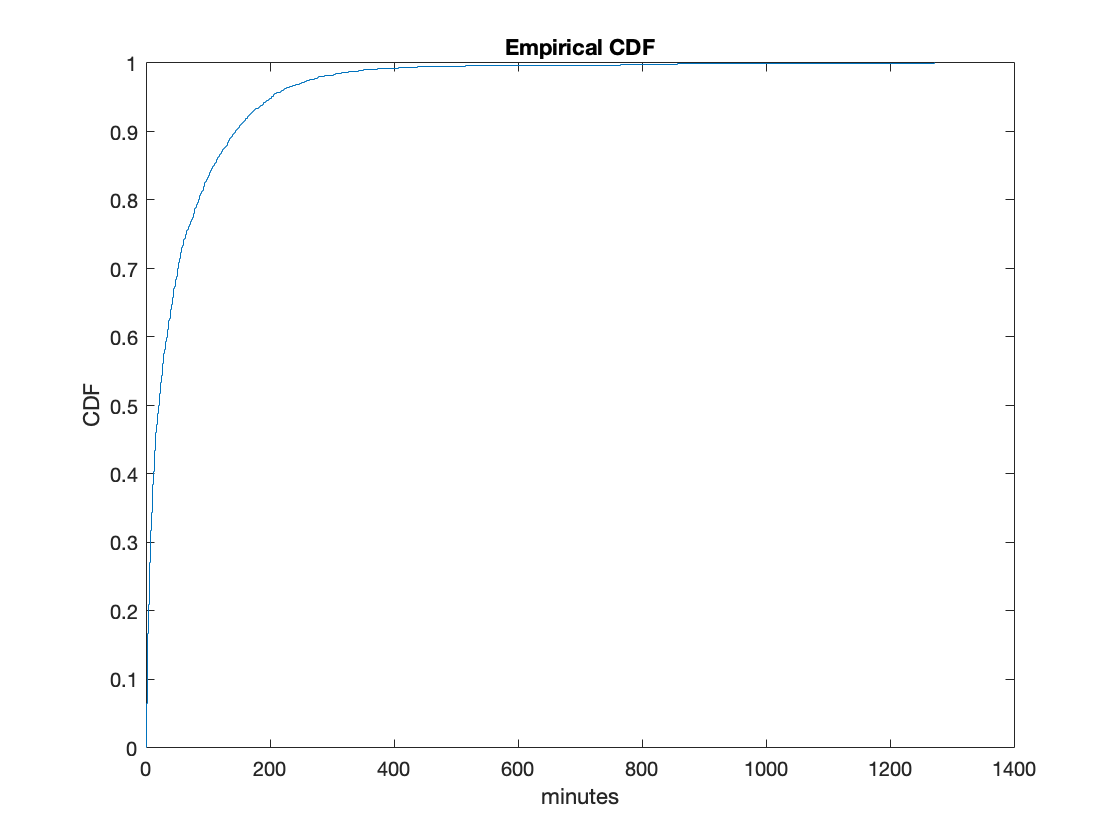


z_mean = mean(Z);
z_var = var(Z);

% Plot the CDF
[f, x] = ecdf(Z);

stairs(x, f)
title('Empirical CDF')
xlabel('minutes')
ylabel('CDF')